### **João Luiz de Castro - UFC**

## `DC motor analysis using LMI approach:`

clear all
close all
clc

DC motor especification:

Leq = 0.1;
Req = 0.2;
J = 1;
B1 = 0.1;
B2 = 1;
Ka = 1;

Matrix definition:

A1 = [-Req/Leq 0; Ka/J -B1/J];
A2 = [-Req/Leq 0; Ka/J -B2/J];
B = [1/Leq; 0];
C = [0 1];
D = 0;

System:

[m n] = size(B)

m = 2

n = 1

Q = sdpvar(n,n,'symmetric');
Y = sdpvar(n,m);

LMI = [Q>=0];
LMI = [LMI,(A1*Q-B*Y)+(A1*Q-B*Y)'<=0];
LMI = [LMI,(A2*Q-B*Y)+(A2*Q-B*Y)'<=0];

optimize(LMI);

SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 3, order n = 6, dim = 10, blocks = 3
nnz(A) = 11 + 0, nnz(ADA) = 9, nnz(L) = 6
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.15E+03 0.000
  1 :   0.00E+00 1.13E+02 0.000 0.0987 0.9900 0.9900   1.00  1  0  8.1E+00
  2 :   0.00E+00 3.13E+00 0.000 0.0276 0.9900 0.9900   1.00  1  1  2.2E-01
  3 :   0.00E+00 6.79E-05 0.000 0.0000 1.0000 1.0000   1.00  1  1  4.8E-06
  4 :   0.00E+00 8.13E-12 0.000 0.0000 1.0000 1.0000   1.00  1  1  1.7E-12

iter seconds digits       c*x               b*y
  4      0.2   Inf  0.0000000000e+00  0.0000000000e+00
|Ax-b| =   2.9e-13, [Ay-c]_+ =   0.0E+00, |x|=  3.5e-14, |y|=  9.5e-01

Detailed timing (sec)
   Pre          IPM          Post
1.040E-01    2.020E-01    7.996E-03    
Max-norms: ||b||=0, ||c|| = 0,
Cholesky |add|=0, |skip| = 0, ||L.L|| = 3.44932.


checkset(LMI)

 
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|               Constraint|   Primal residual|   Dual residual|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Elementwise inequality|            0.9375|      4.6832e-15|
|   #2|        Matrix inequality|            0.1875|      6.9873e-15|
|   #3|        Matrix inequality|                 1|      6.4454e-15|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
| A primal-dual optimal solution would show non-negative residuals. |
| In practice, many solvers converge to slightly infeasible         |
| solutions, which may cause some residuals to be negative.         |
| It is up to the user to judge the importance and impact of        |
| slightly negative residuals (i.e. infeasibilities)                |
| https://yalmip.github.io/command/check/                           |
| https://yalmip.github.io/faq/solutionviolated/                    |
++++++++++++++++++


Ys = value(Y)

Ys =    -0.1375    0.0937


Qs = value(Q)

Qs = 0.9375


K = Ys+inv(Qs)

K =     0.9292    1.1604



e1 = eig(A1-B*K)

e1 =   -10.1353
   -1.2563


e2 = eig(A2-B*K)

e2 =   -10.0027
   -2.2890


Time analysis:

sys1 = ss(A1-B*K,B,C,D)

sys1 =
 
  A = 
           x1      x2
   x1  -11.29   -11.6
   x2       1    -0.1
 
  B = 
       u1
   x1  10
   x2   0
 
  C = 
       x1  x2
   y1   0   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



sys2 = ss(A2-B*K,B,C,D)

sys2 =
 
  A = 
           x1      x2
   x1  -11.29   -11.6
   x2       1      -1
 
  B = 
       u1
   x1  10
   x2   0
 
  C = 
       x1  x2
   y1   0   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.




t = 0:0.1:20;
x = zeros(m,length(t));
x(:,1) = [0 1]';

Runge-Kutta 4th order method:

for i=1:length(t)
    b(i) = 0.1+0.9*rand;
    Acl = [-Req/Leq 0;Ka/J -b(i)/J];
    k1 = (Acl-B*K)*x(:,i);
    k2 = (Acl-B*K)*(x(:,i)+0.5*0.1*k1);
    k3 = (Acl-B*K)*(x(:,i)+0.5*0.1*k2);
    k4 = (Acl-B*K)*(x(:,i)+0.5*k3);
    x(:,i+1) = x(:,i)+(0.1/6)*(k1+2*(k2+k3)+k4);
end

Ycl = C*x;

Using differential equation representation:

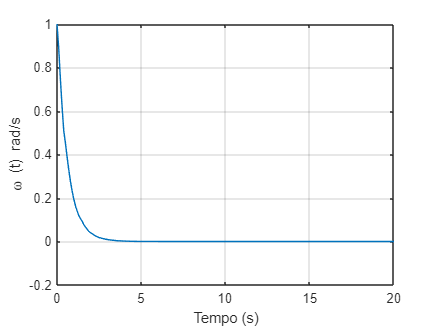

figure(1)
plot(t,Ycl(1:end-1))
xlabel('Tempo (s)')
ylabel('\omega (t) rad/s')
grid on

Using its transfer function:

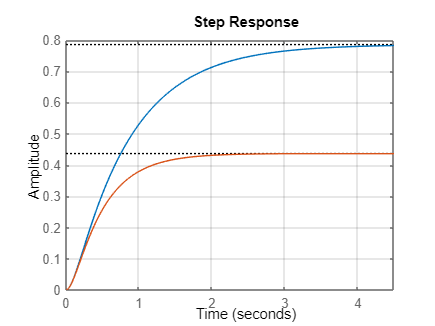

figure(2);
Gcl1 = ss(A1-B*K,B,C-D*K,D);
step(Gcl1)
hold on
grid on
Gcl2 = ss(A2-B*K,B,C-D*K,D);
step(Gcl2)